clear
close all
clc

% Load OCP data from Excel files
file1 = 'nopitting area.xlsx';
file2 = 'pitting area.xlsx';

% Read data from both Excel files (assuming both are in the first sheet)
Area_non_pitting = xlsread(file1, 1);  % Non-pitting data
Area_pitting = xlsread(file2, 1);          % Pitting data

% Generate fake pitting values (0 or 1) for non-pitting and pitting data
pitting_non_pitting = zeros(length(Area_non_pitting), 1); % Non-pitting: pitting = 0
pitting_pitting = ones(length(Area_pitting), 1);          % Pitting: pitting = 1

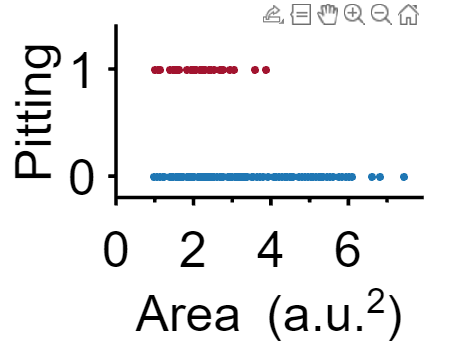

% Plot both sets of points as a scatter plot
figure;
hold on;

% Plot non-pitting data (blue)
scatter(Area_non_pitting, pitting_non_pitting, 20, 'filled');

% Plot pitting data (red)
scatter(Area_pitting, pitting_pitting, 20,'filled');

% Set the axis limits and ticks based on the data range
xlim([0 7.9])  % Adjust x-axis limits
xticks(0:2:8) 

ylim([-0.2 1.4])  % Adjust y-axis limits
yticks(0:1:1.5)

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 1:2:8; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = 0.5:1:2; % Minor ticks which don't line up with majors

% Format the plot
set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', ...
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal');

newcolors = {'#1f77b4', '#A2142F'};
colororder(newcolors)

xlabel('Area (a.u.^2)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')
ylabel('Pitting', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28, 'Color', 'black')